# Steady-state flow recirculation zone around a well doublet

Flow recirculation zones around one or many pairs of injection-extraction wells occur in many practical groundwater flow, reservoir engineering and geothermal engineering problems. Typical application examples are capture zone delineation, forced-gradient tracer tests for aquifer characterization, in-situ remediation of contaminated groundwater, thermogeological assessment of open-loop well-doublet schemes, seasonal heat storage and recovery, and cold fluid reinjection into produced geothermal reservoirs. 

The purpose of this modelling exercise is to simulate steady-state flow patterns around a pair of injection and production wells which are supposed to inject back pumped water with the same flow rate. 

Problem dimensions and aquifer characteristics used in this tutorial are patterned following the mean characteristics of the carbonates Dogger geothermal reservoir layer which is a mildly 1500 meters deep hot aquifer in the Paris basin. It represents the only operational low-enthalpy geothermal system in France since the 1980's. 

We will go through the following steps to build a simulation script modelling the steady-state flow patterns around one doublet in this geothermal reservoir:

- Setup the computational grid, wells positions, flow rates, and fluid properties.

- Perform a steady-state flow simulation around the well pair. 

- Visualize the overpressure distribution in the recirculating zone. 

- Compute and visualize flow streamlines in this zone. 

- Compare numerically computed streamlines with analytical solutions derived from the complex potential theory for two-dimensional homogeneous and isotropic Dupuit-Forcheimer aquifers. 

## Computational grid, wells, and fluid properties setup 

Let's first specify the simple aquifer geometry which is a one layer model of 6000m x 6000m x 25m along each space dimension.

% Domain size along X, Y & Z directions
Dx = 6000; Dy = 6000; Dz = 25;

Next, we set the number of grid cells along each direction. Herein we choose a uniform grid spacing equal to 25m along X and Y directions in the horizontal plane. Next, let `N` to equal the number of grid cells (or elements) in the model.

Nx = 240;  Ny = 240;  Nz = 1;
N  = Nx*Ny*Nz;
Grid.Nx = Nx; Grid.Ny = Ny; Grid.Nz = Nz; Grid.N = N;

To fullfill the need of internal compuattional tasks we add the uniform grid spacings, `hx`, `hy`, and `hz`, along the respective directions to the `Grid` structure

Grid.hx = (Dx/Nx); Grid.hy = (Dy/Ny); Grid.hz = (Dz/Nz);

Additionally, we need to setup other few variables for the `Grid` structure such as, `V` (the uniform cells volume), and `K` (the tintrinsic permeability tensor). Notice that the permeability data is a 3D shape array whose size is 3*Nx*Ny*Nz. The MATLAB command [`ones`](https://fr.mathworks.com/help/matlab/ref/ones.html)`(3,Nx,Ny,Nz)` constructs such an array with a unit values for all cells, and thus by multiplying it with a constant unit Darcy we obtain an isotropic and homogeneous distribution of the permeability data over the computational domain. 

darcy = 9.869233e-13;         % factor for conversion from Darcy to SI units 
Grid.V = (Dx/Nx)*(Dy/Ny)*(Dz/Nz);
Grid.K = darcy*ones(3,Nx,Ny,Nz);

Next, we construct a cartesian grid `G` data structure from the domain extents and spacings. This will help to do the plotting commands more efficiently.   

G = cartGrid(0:Dx/Nx:Dx, 0:Dy/Ny:Dy);

Before setting the flow rates we define some useful constants to convert between time units

second = 1; 
minute = 60*second; 
hour   = 60*minute; 
day    = 24*hour; 
month  = 30*day;
year   = 365*day;

We set the injection and production flow rates equal to +150$m^3/h$ and -150$m^3/h$, respectively. Notice that (by convention) injection flow rates are positive and production ones are negrative. `Qw` is the well rates array. It is null everywhere except at cell numbers where the wells are located. 

wells_pos = [91,150];              % cell no's of the injection and production wells respectively
Q  = 150/hour;                     % conversion from m^3/h to m^3/s
Qw = zeros(N,1);                   % initialization
Qw(wells_pos) = Q*[+1,-1];         % injection/production wells flow rates

Finally, we setup the fluid properties by initializing a `Fluid` object named 'water' with user-defined constant density and viscosity properties equal to $10^3Kg/m^3$ and $10^{-3}Pa.s$ respectively. 

% fluid properties units: density [Kg/m^3], viscosity [Pa.s]
water = Fluid('water',[1000, 1e-3]);

## Steady-state flow simulation

To simulate steady-state flow we simply call the `Pressure` solver. In this flow regime this function needs only three input arguments: the computational grid, `G3`, the fluid, `water`, and the array of flow rates, `Qw`. 

Pascal = 1;
bar    = 1e5*Pascal;               % conversion from bar to Pascal units

% call flow solver for single-phase flow
tic; [P,V] = Pressure(Grid,water,Qw); toc;

Elapsed time is 0.747978 seconds.


## Overpressure distribution in the recirculation zone

The overpressure distribution arround the wells doublet is plotted using the `PlotContourData` function. Here, we call [`figure`](https://fr.mathworks.com/help/matlab/ref/figure.html) command to open a new figure window so that all next plotting commands will be directed into it. The plot is presented with contour levels between the min and max levels of overpressure around *-25 bar* and 25* bar* respectively with 1.25 bar interval. We use the [`jet`](https://fr.mathworks.com/help/matlab/ref/colormap.html) [`colormap`](https://fr.mathworks.com/help/matlab/ref/colormap.html) with 41 levels of colors equating thus the number of intervals between contour lines, thus producing a plot in which each region between two succesive contour lines is filled with a unique color. 

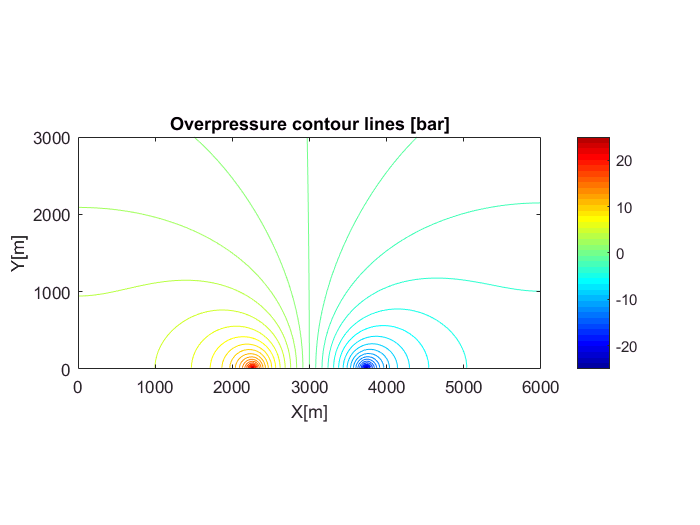

figure; 
% plot overpressure in the domain
opts.fill = 'off';
PlotContourData(G, P(:)/bar, opts,'LevelList',-25:1.25:25);
colormap(jet(41));
axis tight equal; axis([0,6000,0,3000]); colorbar; 
title('Overpressure contour lines [bar]'); xlabel('X[m]'); ylabel('Y[m]');

As expected the flow pattern is perfectly symmetrical around the median y-axis of the rectangular domain and the contour lines are orthogonal to no-flow boundaries according to the classical groundwater flownet theory. 

## Streamlines in the recirculation zone

Now, we will calculate and plot the streamlines (lines tangent to velocities) starting from an equal distribution of points along the median y axis. We set massless particle tracking directions forwards towards the producer and backwards towards the injector. Next, we plot the two different sets of forward and backward streamlines with different colors. 

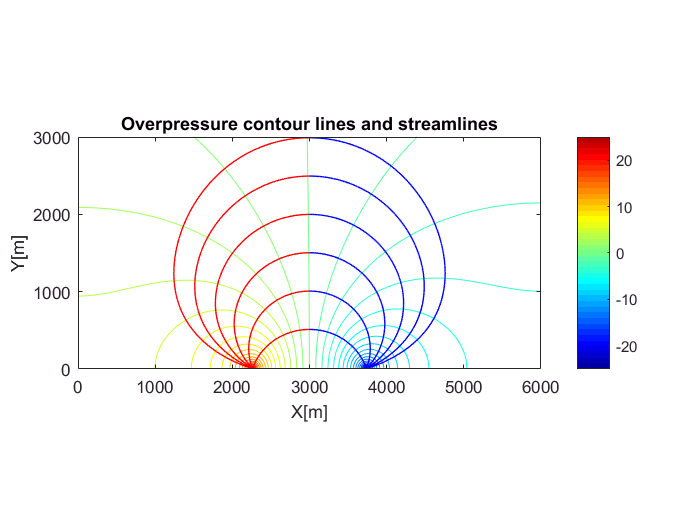

h = [Dx/Nx, Dy/Ny];                        % uniform grid sizes along X & Y
sx = 3000*ones(1,7);                       % streamlines starting x positions
sy = linspace(0.5*h(2),(Ny-0.5)*h(2)/2,7); % streamlines starting y positions
hold on;                                   % keep drawing to last plot
hp = PlotStreamline(V,h,sx,sy,true);       % plot streamlines in forward direction ...
set(hp,'Color','b','LineWidth',0.8);       %    with blue color 
hi = PlotStreamline(V,h,sx,sy,false);      % plot streamlines in backward direction ... 
set(hi,'Color','r','LineWidth',0.8);       %    with red color
title('Overpressure contour lines and streamlines');

Here again, the obtained streamlines are orthogonal to pressure (and therefore discharge potential) contour lines as expected from the flownet theory for stedy-state two-dimensional groundwater flow in homogeneous and isotropic aquifers. 

## Comparison to analytical solution

When considering groundwater flow in homogeneous and isotropic confined aquifers, Bear (1979) and Strack (1989) have used the complex potential theory to analytically derive the expressions for its discharge potential, $\Phi$, and the streamfunction, $\Psi$, components assuming the Dupuit-Forcheimer conditions. The complex potential is given as


$$\Omega(z) = \Phi(z) + i \Psi(z)$$


where $z=x+iy$ is the coordinate in the complex plane. 

In the recirculation zone created by a pair of of injection and extraction wells in absence of regional flow these functions are given as 


$$\Phi(x,y) = \frac{Q}{4\pi} \ln [\frac{(x-d)^2+y^2}{(x+d)^2+y^2}]$$



$$\Psi(x,y) = \frac{Q}{2\pi}[\arctan(\frac{y}{x-d})-\arctan (\frac{y}{x+d})]$$


where $d$is the half-distance between the wells.

The equipotential lines are concentric circles centered at the injection and production wells. Their analytic expressions are given by Strack (1989) as

$[x+d\coth(\frac{2\pi\Phi}{Q})]^2 + y^2 = \frac{d^2}{\sinh^2(\frac{2\pi\Phi}{Q})}$   if  $\Phi \ne 0$

$x=0$                                                  if $\Phi = 0$

The streamlines have also circular shapes and their center are located in the median vertical axis between the well pair. They're analytically expressed as 

$x^2 + [y-d\cot(\frac{2\pi\Psi}{Q})]^2 = \frac{d^2}{sin^2(\frac{2\pi\Psi}{Q})}$   if $\Psi \ne 0, \pm\frac{Q}{2}$ 

$y=0$                                             if $\Psi = 0, \pm\frac{Q}{2}$

It is easy to show that coordinates of the streamline, $\Psi$, center are $[0,d\cot(2\pi\Psi/Q)]$and that its radius is $d/|\sin(2\pi\Psi/Q)|$. The height of streamline arc is $h_s = d\tan(\frac{\pi}{2}-\frac{\pi|\psi|}{Q})$(Luo and Kitanidis, 2004).

Now, let's calculate the $\Psi$ levels of numerically calculated streamlines from their prescribed heights. 

d   = 1500/2;
psi = Q*((pi/2)-atan(sy(2:end)/d))/pi;

Now, we plot few points of the corresponding circles for each streamline except the first one corresponding to the straight line connecting the two wells. 

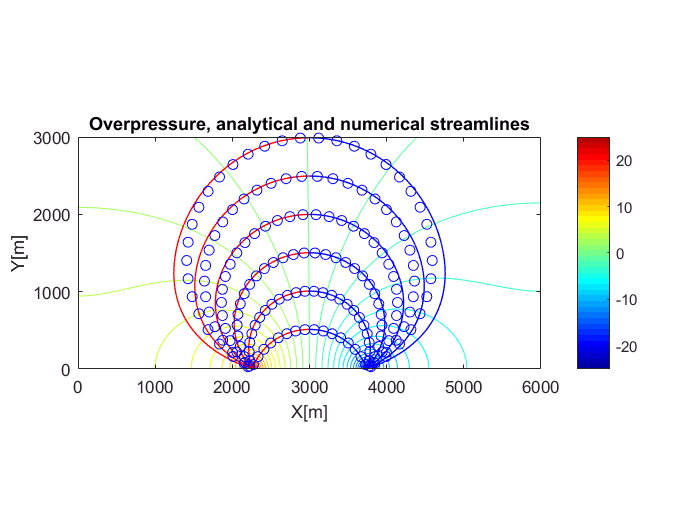

rc = d./abs(sin(2*pi*psi/Q));
yc = d*cot(2*pi*psi/Q);
for i=1:numel(rc)
    xp = rc(i)*cos(-pi:pi/21:pi)+Dx/2; 
    yp = rc(i)*sin(-pi:pi/21:pi)+yc(i); 
    plot(xp,yp,'bo');
end
title('Overpressure, analytical and numerical streamlines');

As shown in the last figure the agreement between the numerically computed streamlines (plotted in solid lines) and the analytically calculated ones (represented by circles) is quite good. The quality of this agreement deteriorates for the longest streamlines connecting the wells. This is a boundary condition artifact since those streamlines become closer to the closed domain boundaries, unlike in the analytical derivations assuming an infinite domain extent. This error should not be attributed to numerical issues associated with the pressure solver or the streamlines integrator. This could be easily checked by decreasing the grid size in both directions showing to have negligeable impact on the numerical solution accuracy. 

## Conclusions

In this tutorial we learned how to make a simple script to design the recirculation zone around a well doublet in a geothermal reservoir to establish the initial steady-state flow patterns prior to a heat transport simulation. 

Numerically calculated and visualized flow streamlines delineating the recirculation zone are compared to analytic expressions derived from the complex potential theory. A good agreement is observed between these two solutions demonstrating the accuracy of the flow solver and the streamlines tracer. 

This tutorial could be easily adapted to jump-start other applications. For instance, in capture zone delineation problems the variable of interest is the volume of each recirculation zone around one doublet or a complex system of hydraulically connected wells. Otherwise, for in-situ remediation or tracer test problems we need to consider the residence or arrival times. 

## References

Bear, J. (1979). *Hydraulics of Groundwater*. McGraw-Hill, New York. 

Luo, J., and P.K. Kitanidis (2004). Fluid residence times within a recirculation zone created by an extraction-injection well pair. *J. Hydrology*, 295, 149-162. 

Strack, O.D.L. (1989). *Groundwater Mechanics*, Prentice-Hall, Englewood Cliffs, NJ. 